# EJERCICIO 1

En la Figura se indica las propiedades de u edificio de 3 pisos. Los datos incluyen los pesos de los niveles, las rigideces por entrepiso y las frecuencias y modos naturales. Se pide deducir la **matriz de amortiguamiento de Rayleigh** de tal manera que la fracción de amortiguamiento sea del 5% para el primero y segundo modo. ***Determinar la fracción de amortiguamiento para el tercer modo.***

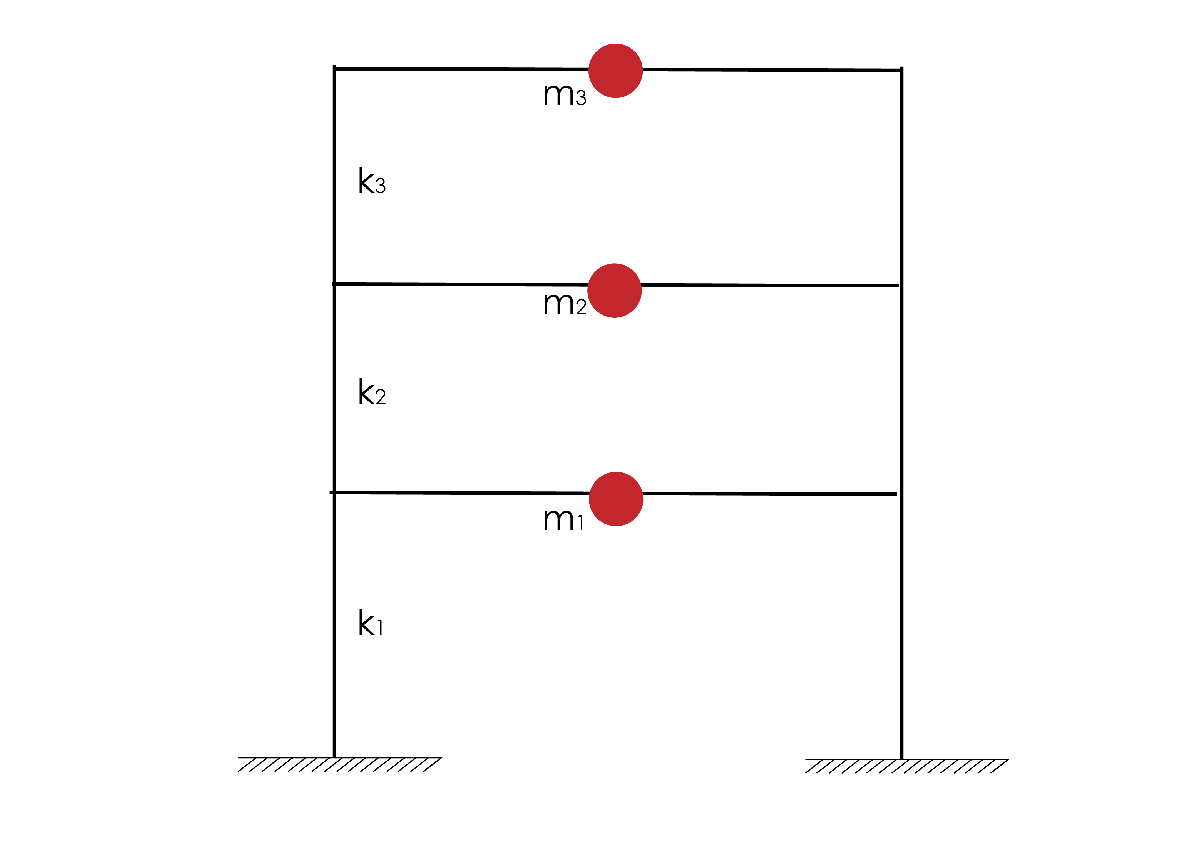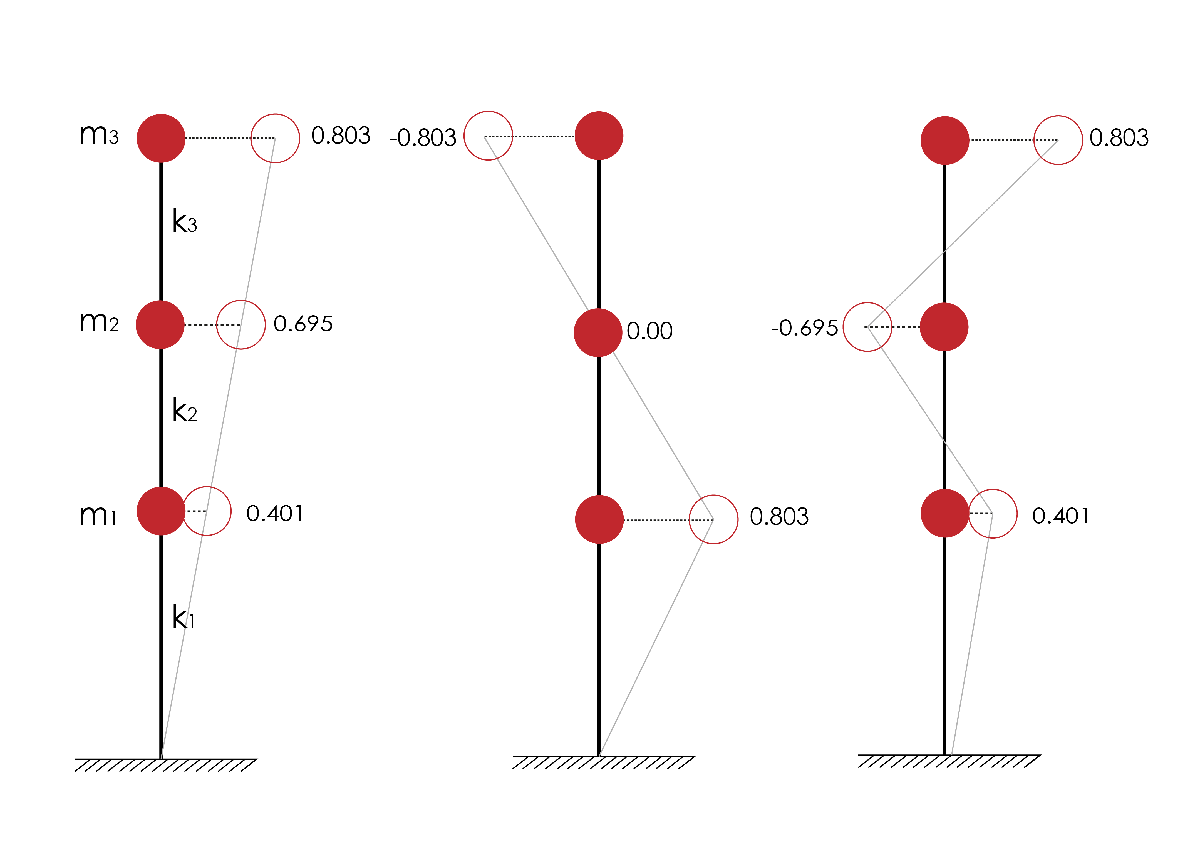

## **DATOS**

Los ***pesos por niveles*** son:

 $p_1 =p_{2\;} =200\;\textrm{Tn}$ y $p_3 =100\;\textrm{Tn}$

Las*** rigideces de entre piso ***son:


$$k_1 =k_{2\;} =k_{3\;} =120\;\frac{\textrm{Tn}}{\textrm{cm}}$$


Las** frecuencias modales** son:


$$\omega_{\textrm{n1}} =12\ldotp 57\;\frac{\textrm{rad}}{\textrm{seg}}\;;\omega_{\textrm{n2}} =33\ldotp 34\;\frac{\textrm{rad}}{\textrm{seg}}\omega_{\textrm{n3}} =46\ldotp 89\;\frac{\textrm{rad}}{\textrm{seg}}\;$$


Y los **modos naturales **son**:**


$$\phi_1 =\left\lbrack \begin{array}{c}
0\ldotp 401\\
0\ldotp 695\\
0\ldotp 803
\end{array}\right\rbrack ;\;\;\;\phi_2 =\left\lbrack \begin{array}{c}
0\ldotp 803\\
0\ldotp 000\\
-0\ldotp 803
\end{array}\right\rbrack ;\;\;\;\;\phi_3 =\left\lbrack \begin{array}{c}
0\ldotp 401\\
-0\ldotp 695\\
0\ldotp 803
\end{array}\right\rbrack$$


format short
p1 = 200;   %% [Tn] - Peso del nivel 1
p2 = 200;   %% [Tn] - Peso del nivel 2
p3 = 100;   %% [Tn] - Peso del nivel 3
k1 = 120;   %% [Tn/cm] - Rigidez del 1 entrepiso
k2 = 120;   %% [Tn/cm] - Rigidez del 2 entrepiso
k3 = 120;   %% [Tn/cm] - Rigidez del 3 entrepiso
g  = 981;   %% [cm/s2] - Gravedad
w1 = 12.57; %% [rad/seg] - frecuencia modal del piso 1
w2 = 33.34; %% [rad/seg] - frecuencia modal del piso 2
w3 = 46.89; %% [rad/seg] - frecuencia modal del piso 3
phi1 = [0.401; 0.695; 0.803];  %% modo 1 natural 
phi2 = [0.803; 0.000;-0.803];  %% modo 2 natural 
phi3 = [0.401;-0.695; 0.803];  %% modo 3 natural 

## **SOLUCIÓN:**

Y vamos a solucionar el sistema mediante la **matriz de amortiguamiento de Rayleigh **$\left\lbrack C\right\rbrack$**, **que es uno de los métodos clásicos.


$$\left\lbrack C\right\rbrack =a_0 m+a_1 k$$


Donde los factores $a_0$ y $a_1$ son constantes cuyos valores son: $s^{-1\;}$y $s$ respectivamente. A partir de esto vamos a obtener las **matriz de masa **$\left\lbrack m\right\rbrack$** y matriz de rigidez **$\left\lbrack k\right\rbrack$. Tal que, para 3 niveles, tendremos:


$$m_1 =m_2 =\frac{W_n }{g}=\frac{\left(200\textrm{Tn}\right)}{9\ldotp 81\frac{\textrm{cm}}{s^2 }}=0\ldotp 204\;;\;\;\;\;\;m_3 =\frac{W_n }{g}=\frac{\left(100\textrm{Tn}\right)}{9\ldotp 81\frac{\textrm{cm}}{s^2 }}=0\ldotp 102\ldotp$$



$$\left\lbrack m_{n\;} \right\rbrack =\left\lbrack \begin{array}{cccc}
m_1  & 0 & \ldotp \ldotp \ldotp  & 0\\
0 & m_2  & \; & \;\\
\ldotp  & \; & \ldotp \ldotp \ldotp  & \;\\
0 & \; & \; & m_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\;m_1  & 0 & 0\\
0 & m_2  & 0\\
0 & 0 & m_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\;0\ldotp 204 & 0 & 0\\
0 & 0\ldotp 204 & 0\\
0 & 0 & 0\ldotp 102
\end{array}\right\rbrack$$
 

Y para la matriz de rigidez tenemos la solucion tal que:


$$\left\lbrack k_n \right\rbrack =\left\lbrack \begin{array}{cccc}
k_{11}  & k_{12}  & \ldotp \ldotp \ldotp  & {\textrm{k1}}_n \\
k_{21}  & k_{22}  & \; & \;\\
\ldotp  & \; & \ldotp \ldotp \ldotp  & \;\\
k_{\textrm{m1}}  & \; & \; & k_{\textrm{mn}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\;k_1 +k_2  & -k_2  & 0\\
-k_2  & k_2 +k_3  & -k_3 \\
0 & k_3  & k_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\;240 & -120 & 0\\
-120 & 240 & -120\\
0 & -120 & 120
\end{array}\right\rbrack$$


%% Calculo de masa
m1 = p1/g;
m2 = p2/g;
m3 = p3/g;

m = [m1 0 0; 0 m2 0; 0 0 m3]       %% Matriz de masa [m]

m =     0.2039         0         0
         0    0.2039         0
         0         0    0.1019


k = [k1+k2 -k2 0; -k2 k2+k3 -k3; 0 -k3 k3] %% Matriz de rigidez [k]

k =    240  -120     0
  -120   240  -120
     0  -120   120


Y ahora, nosotros tenemos que usas la sigiente ecuación:


$$\left\lbrack \begin{array}{c}
\zeta_i \\
\zeta_j 
\end{array}\right\rbrack =\frac{1}{\;2}\left\lbrack \begin{array}{cc}
\frac{1}{\omega_i } & \omega_i \\
\frac{1}{\omega_j } & \omega_j 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 
\end{array}\right\rbrack$$


Y finalmente vamos a despejar y resolver la ecuación


$$2\left\lbrack \begin{array}{c}
\zeta_i \\
\zeta_j 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{1}{\omega_i } & \omega_i \\
\frac{1}{\omega_j } & \omega_j 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 
\end{array}\right\rbrack \;\;\;\Rightarrow \;\;2\left\lbrack \begin{array}{c}
0\ldotp 05\\
0\ldotp 05
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\frac{1}{12\ldotp 57} & 12\ldotp 57\\
\frac{1}{34\ldotp 33} & 34\ldotp 33
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 
\end{array}\right\rbrack \Rightarrow \;\;\left\lbrack \begin{array}{c}
0\ldotp 1\\
0\ldotp 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 0796 & 12\ldotp 57\\
0\ldotp 0291 & 34\ldotp 33
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 
\end{array}\right\rbrack$$
 

Y resolvemos, por el **Método de la matrix Inversa **$\left\lbrack \textrm{AX}=B\right\rbrack$


$$X=A^{-1} B$$


### RESOLUCIÓN POR EL MÉTODO DE LA MATRIZ INVERSA PARA LOS COEFICIENTES [a0 y a1]

Entonces nosotros vamos a considerar las secciónes de la siguiente manera:


$$A=\left\lbrack \begin{array}{cc}
\;0\ldotp 0796 & 12\ldotp 57\\
0\ldotp 0291 & 34\ldotp 33
\end{array}\right\rbrack ,y\;B=\left\lbrack \begin{array}{c}
\;0\ldotp 1\\
0\ldotp 1
\end{array}\right\rbrack$$


Entonces, calcularemos $A^{-1}$ cuya solución en este caso estará en función de la siguiente ecuación:


$$A^{-1\;} =\frac{1}{\;\textrm{det}\left\lbrack \begin{array}{cc}
\;a & b\\
c & d
\end{array}\right\rbrack }\left\lbrack \begin{array}{cc}
\;d & -b\\
-c & a
\end{array}\right\rbrack$$


zeta1 = 0.05;
zeta2 = 0.05;
wi    = w1;
wj    = w2;
B     = 2.*[zeta1 zeta2]';
%% Solución del sistema matricial
A       = [1/wi wi; 1/wj wj] 

A =     0.0796   12.5700
    0.0300   33.3400


A_i     = inv(A)

A_i =    14.6529   -5.5245
   -0.0132    0.0350


X       = A_i*B

X =     0.9128
    0.0022


a0      = X(1,:)

a0 = 0.9128

a1      = X(2,:)

a1 = 0.0022

### SOLUCIÓN DE LA MATRIZ DE AMORTIGUAMIENTO DE RAYLEIGH

Conociendo que entonces, $C=a_o m+a_1 k$ solo tenemos que reemplazar los valores al sistema:


$$c=a_o m+a_1 k=0\ldotp 9128$$

$$\left\lbrack \begin{array}{ccc}
\;0\ldotp 204 & 0 & 0\\
0 & 0\ldotp 204 & 0\\
0 & 0 & 0\ldotp 102
\end{array}\right\rbrack +0\ldotp 0022\left\lbrack \begin{array}{ccc}
\;240 & -120 & 0\\
-120 & 240 & -120\\
0 & -120 & 120
\end{array}\right\rbrack$$


c0  = a0*m   %% matriz de amortiguamiento de Rayleigh para el modo 1  

c0 =     0.1861         0         0
         0    0.1861         0
         0         0    0.0931


c1  = a1*k   %% matriz de amortiguamiento de Rayleigh para el modo 2

c1 =     0.5228   -0.2614         0
   -0.2614    0.5228   -0.2614
         0   -0.2614    0.2614


C   = c0 + c1

C =     0.7089   -0.2614         0
   -0.2614    0.7089   -0.2614
         0   -0.2614    0.3544



$$c=\left\lbrack \begin{array}{ccc}
\;0\ldotp 7089 & -0\ldotp 2614 & 0\\
-0\ldotp 2614 & 0\ldotp 7089 & -0\ldotp 2614\\
0 & 0\ldotp 2614 & 0\ldotp 3544
\end{array}\right\rbrack$$


### OBTENCIÓN DEL $\zeta_3$ PARA EL 3er NIVEL

Determinaremos esta fracción de amortiguamiento, con las ecuaciónes anteriormente revisada. Así:


$$\xi_{n=3\;} =\left(\frac{a_0 }{\;2}\frac{\;1}{{\omega \;}_{\textrm{n3}} }\right)+\left(\frac{a_1 }{2}\omega_{\textrm{n3}} \right)=\frac{0\ldotp 9128}{2\left(46\ldotp 89\right)}+\left(\frac{0\ldotp 0022}{2}46\ldotp 89\right)=0\ldotp 0608\approx 6\ldotp 08%$$


zeta_3 = ((a0/2)*(1/w3))+((a1/2)*w3)

zeta_3 = 0.0608

# EJERCICIO 2

Con los datos del ejercicio anterior, evaluar la matriz de amortiguamiento clásico si la fracción de amortiguamiento es del 5% para los 3 modos. **Aplicar los conceptos del Amortiguamiento de Caughey.**

En este caso nosotros usaremos la **serie de Caughey, **misma que es:


$$c=a_0 m+a_1 k+a_2 {\mathrm{km}}^{-1} k$$


Cuya deducción, ya fue explorada. Y que es de donde partiremos para determinar los valores de $a_0 ,a_1$y $a_2$, mediante al ecuación:


$$\xi {\;}_n =\frac{1}{2}\sum_{l=0}^{J-1} a_l \omega_n^{2l-1\;} \;\;\;\;\Rightarrow \xi_n =\left(\frac{a_0 }{2}\frac{\;1}{\omega_{\mathrm{n1}} }\right)+\left(\frac{a_1 }{2\;}\omega_{\mathrm{n2}\;} \right)+\left(\frac{a_3 }{2}\omega_{\mathrm{n3}}^{3\;} \right)$$


Y ahora, nosotros tenemos que usas la sigiente ecuación:


$$\left\lbrack \begin{array}{c}
\;\xi_1 \\
\xi_{2\;} \\
\xi_{3\;} 
\end{array}\right\rbrack =\frac{1}{\;2}\left\lbrack \begin{array}{ccc}
\;\frac{1}{\omega_1 } & \omega_1  & \omega_1^3 \\
\frac{1}{\omega_2 } & \omega_2  & \omega_2^3 \\
\frac{1}{\omega_3 } & \omega_3  & \omega_3^3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 
\end{array}\right\rbrack \Rightarrow 2\left\lbrack \begin{array}{c}
\;\xi_1 \\
\xi_{2\;} \\
\xi_{3\;} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\;\frac{1}{\omega_1 } & \omega_1  & \omega_1^3 \\
\frac{1}{\omega_2 } & \omega_2  & \omega_2^3 \\
\frac{1}{\omega_3 } & \omega_3  & \omega_3^3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 
\end{array}\right\rbrack \;\Rightarrow 2\left\lbrack \begin{array}{c}
\;0\ldotp 05\\
0\ldotp 05\\
0\ldotp 05
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\;\frac{1}{12\ldotp 57} & 12\ldotp 57 & 12\ldotp {57}^3 \\
\frac{1}{34\ldotp 33} & 34\ldotp 33 & 34\ldotp {33}^3 \\
\frac{1}{46\ldotp 89} & 46\ldotp 89 & 46\ldotp {89}^3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 
\end{array}\right\rbrack \;\;\;\;\;$$


### RESOLUCIÓN POR EL MÉTODO DE LA MATRIZ INVERSA PARA LOS COEFICIENTES [a0, a1, y a2]


%% Solución del sistema matricial
A_c     = [1/w1 w1 w1^3; 1/w2 w2 w2^3; 1/w3 w3 w3^3] 

A_c = 	1.0e+05 *

    0.0000    0.0001    0.0199
    0.0000    0.0003    0.3706
    0.0000    0.0005    1.0310


A_ic    = inv(A_c)

A_ic =    15.7874  -11.1732    3.7122
   -0.0214    0.0758   -0.0268
    0.0000   -0.0000    0.0000


zeta3   = 0.05;
B_c     = 2.*[zeta1 zeta2 zeta3]'

B_c =     0.1000
    0.1000
    0.1000


X_c     = A_ic*B_c

X_c =     0.8326
    0.0028
   -0.0000


a0_c    = X_c(1,:)

a0_c = 0.8326

a1_c    = X_c(2,:)

a1_c = 0.0028

a2_c    = X_c(3,:)

a2_c = -4.5659e-07

Y tendremos que, los coeficientes son:


$$\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\;\;\;8\ldotp 3265\;{x\;10}^{-1} \\
\;\;\;2\ldotp 7578\;{x\;10}^{-3} \\
-4\ldotp 5659\;{x\;10}^{-7} 
\end{array}\right\rbrack$$


### SOLUCIÓN DE LA MATRIZ DE AMORTIGUAMIENTO DE CAUGHEY

Y finalmente ensamblaremos el sistema mediante: $c=a_0 m+a_1 k+a_2 {\mathrm{km}}^{-1} k$

c0c  = a0_c*m            %% matriz de amortiguamiento de Caughey para el modo 1  

c0c =     0.1698         0         0
         0    0.1698         0
         0         0    0.0849


c1c  = a1_c*k            %% matriz de amortiguamiento de Caughey para el modo 2

c1c =     0.6619   -0.3309         0
   -0.3309    0.6619   -0.3309
         0   -0.3309    0.3309


c2c  = a2_c*k*(m^-1)*k   %% matriz de amortiguamiento de Caughey para el modo 3

c2c =    -0.1613    0.1290   -0.0323
    0.1290   -0.2258    0.1290
   -0.0323    0.1290   -0.0968


C_c  = c0c + c1c + c2c 

C_c =     0.6704   -0.2019   -0.0323
   -0.2019    0.6059   -0.2019
   -0.0323   -0.2019    0.3191



$$c=\left\lbrack \begin{array}{ccc}
\;\;\;0\ldotp 6704 & -0\ldotp 2019 & -0\ldotp 0323\\
-0\ldotp 2019 & \;\;\;0\ldotp 6059 & -0\ldotp 2019\\
\;\;\;0\ldotp 0323 & \;\;\;0\ldotp 2019 & \;\;\;\;0\ldotp 3191
\end{array}\right\rbrack$$
